# TAP 2

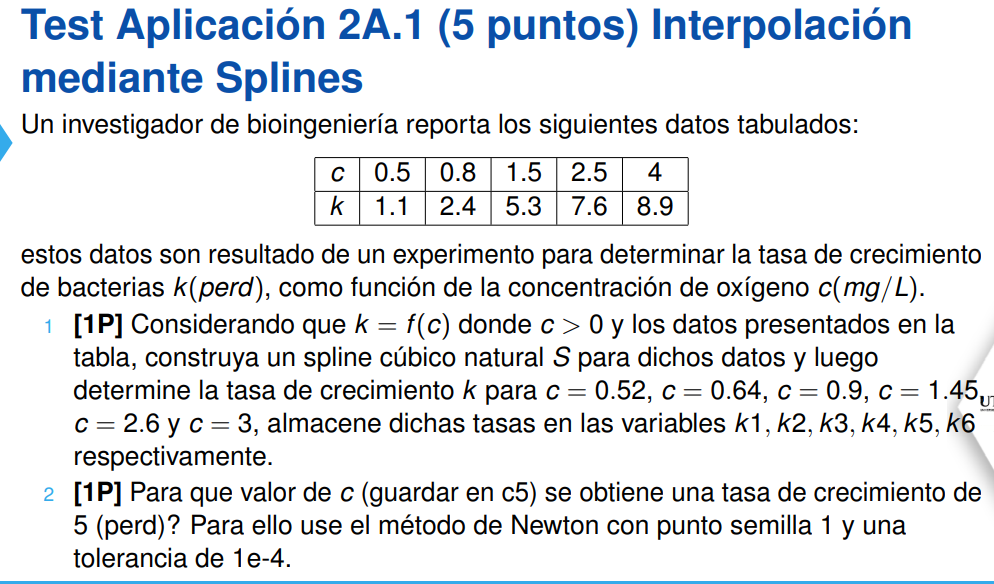

c = [0.5 0.8 1.5 2.5 4];
k = [1.1 2.4 5.3 7.6 8.9];

% item a)
k_c = splinenatural(c,k)

k_c =    0.270620148792741                   0   4.308977519941985   1.100000000000000
  -0.836078593874100   0.243558133913467   4.382044960116025   2.400000000000000
   0.318216098622191  -1.512206913222143   3.493990814599952   5.300000000000000
   0.123901914967905  -0.557558617355571   1.424225284022238   7.600000000000000



% c = 0.52 -> [0.5 - 0.8] (1)
cc = 0.52;
x = c(1);
k1 = k_c(1,1)*((cc - x)^3) + k_c(1,2)*((cc - x)^2) + k_c(1,3)*(cc - x) + k_c(1,4)

k1 =    1.186181715360030



% c = 0.64 -> [0.5 - 0.8] (1)
cc = 0.64;
x = c(1);
k2 = k_c(1,1)*((cc - x)^3) + k_c(1,2)*((cc - x)^2) + k_c(1,3)*(cc - x) + k_c(1,4)

k2 =    1.703999434480165



% c = 0.9 -> [0.8 - 1.5] (2)
cc = 0.9;
x = c(2);
k3 = k_c(2,1)*((cc - x)^3) + k_c(2,2)*((cc - x)^2) + k_c(2,3)*(cc - x) + k_c(2,4)

k3 =    2.839803998756863



% c = 1.45 -> [0.8 - 1.5] (2)
cc = 1.45;
x = c(2);
k4 = k_c(2,1)*((cc - x)^3) + k_c(2,2)*((cc - x)^2) + k_c(2,3)*(cc - x) + k_c(2,4)

k4 =    5.121624451811181



% c = 2.6 -> [2.5 - 4] (4)
cc = 2.6;
x = c(4);
k5 = k_c(4,1)*((cc - x)^3) + k_c(4,2)*((cc - x)^2) + k_c(4,3)*(cc - x) + k_c(4,4)

k5 =    7.736970844143636



% c = 3 -> [2.5 - 4] (4)
cc = 3;
x = c(4);
k6 = k_c(4,1)*((cc - x)^3) + k_c(4,2)*((cc - x)^2) + k_c(4,3)*(cc - x) + k_c(4,4)

k6 =    8.188210727043215


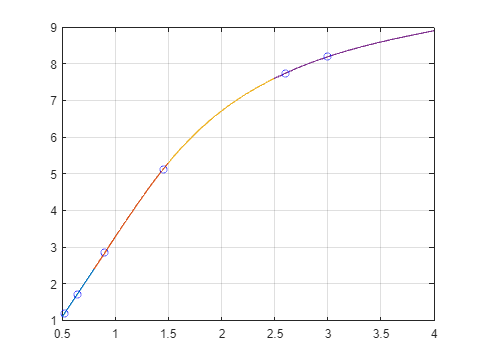


a = [0.52 0.64 0.9 1.45 2.6 3];
b = [k1 k2 k3 k4 k5 k6];

plot(a, b, 'ob')
hold off


% item b)
% k = 5 -> [0.8 - 1.5] (2)

syms x
f = matlabFunction(k_c(2,1)*x^3 + k_c(2,2)*x^2 + k_c(2,3)*x + k_c(2,4))

f = function_handle with value:
    @(x)x.*4.382044960116025+x.^2.*2.435581339134639e-1-x.^3.*8.360785938740979e-1+1.2e+1./5.0



x0 = 1;
Tol = 1e-4;

z = newton(f, x0, Tol);

c5 = z(end)

c5 =   -1.759962362197554


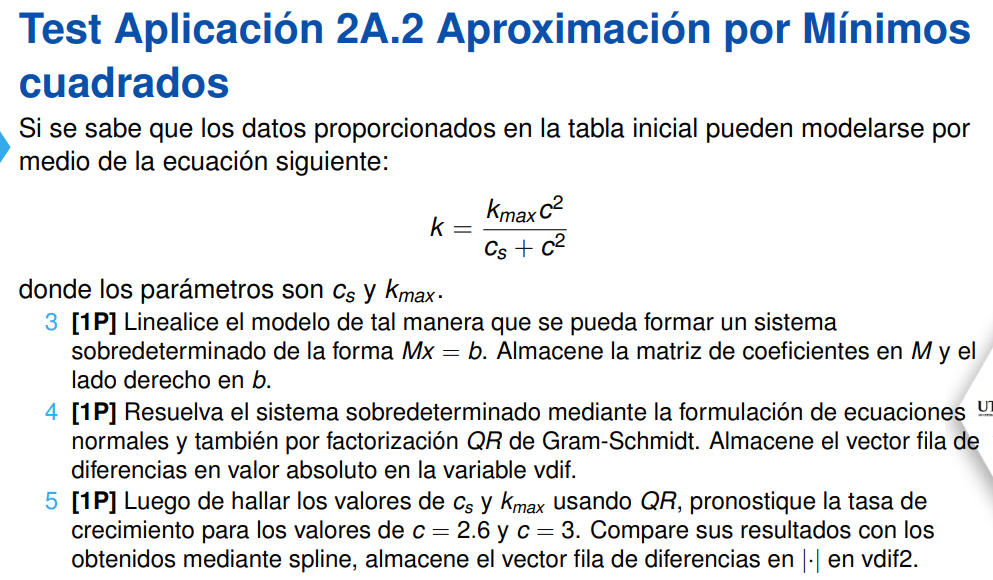

c = [0.5 0.8 1.5 2.5 4];
k = [1.1 2.4 5.3 7.6 8.9];



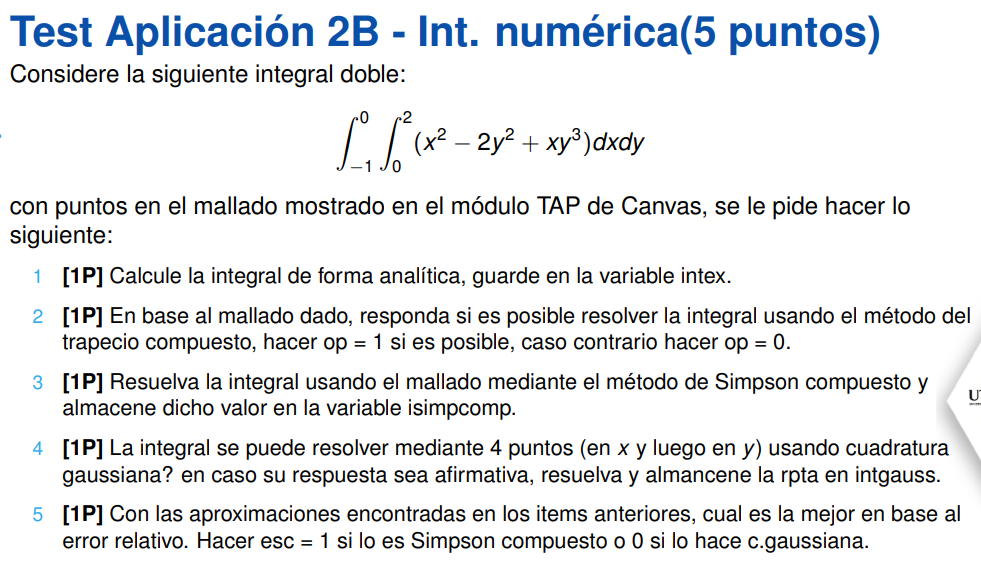

fun = @(x, y) x.^2 - 2.*y.^2 + x.*y.^3

fun = function_handle with value:
    @(x,y)x.^2-2.*y.^2+x.*y.^3


x_limits = [0, 2];
y_limits = [-1, 0];

% item 1)
intex = integral2(fun, x_limits(1), x_limits(2), y_limits(1), y_limits(2))

result =    0.833333333333388



% itme 2)
op = 1



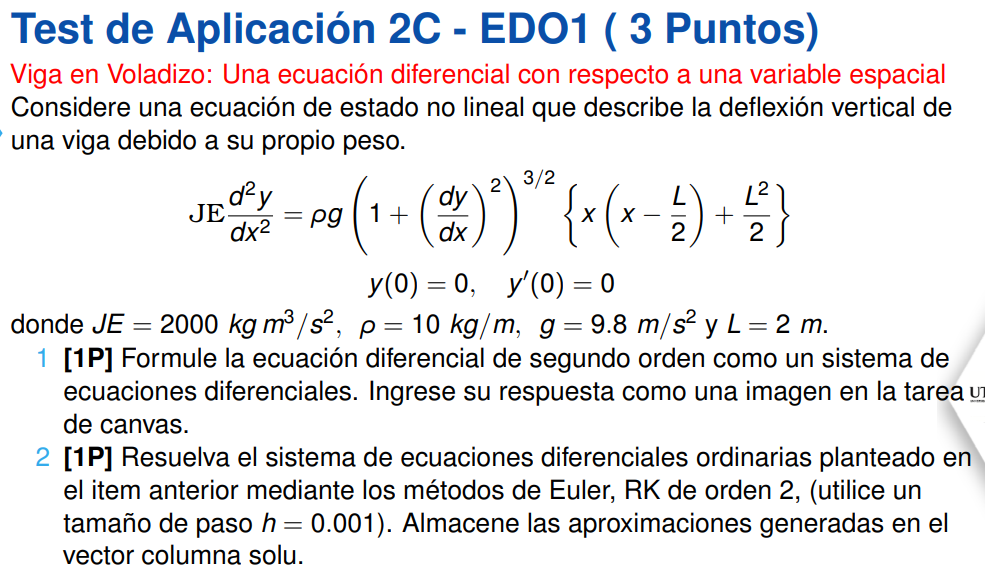

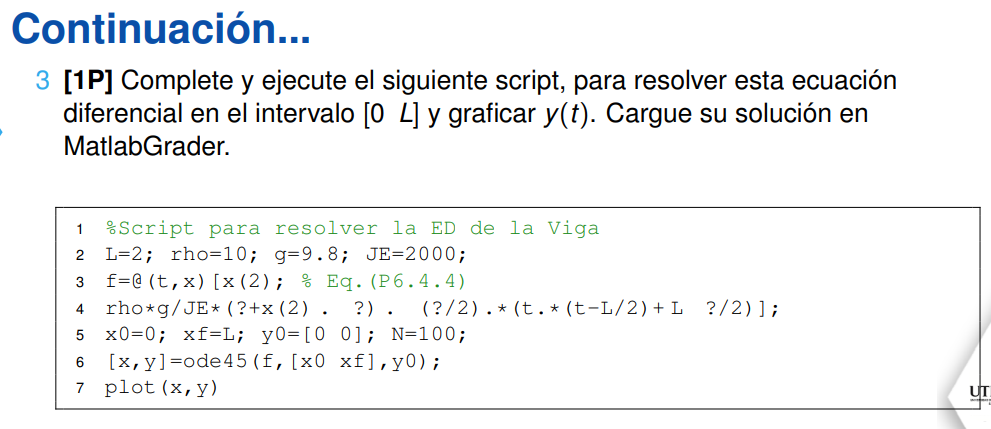

JE = 2000;
p = 10;      
g = 9.8;   
L = 2;

f = @(x, y) [y(2); p*g/JE * (1 + y(2).^2).^(3/2) .* (x .* (x - L/2) + L^2/2)]

f = function_handle with value:
    @(x,y)[y(2);p*g/JE*(1+y(2).^2).^(3/2).*(x.*(x-L/2)+L^2/2)]



x0 = 0; xf = L;
y0 = [0; 0];
N = 100;

[x, y] = ode45(f, [x0 xf], y0)

x =                    0
   0.000512629883982
   0.001025259767963
   0.001537889651945
   0.002050519535926
   0.004613668955834
   0.007176818375742
   0.009739967795649
   0.012303117215557
   0.025118864315096


y =                    0                   0
   0.000000012875581   0.000050231292554
   0.000000051497925   0.000100449722009
   0.000000115860444   0.000150655301947
   0.000000205956552   0.000200848045949
   0.000001042211006   0.000451619702204
   0.000002520821677   0.000702072496850
   0.000004640973452   0.000952208126847
   0.000007401855563   0.001202028288804
   0.000030789148510   0.002446456436043


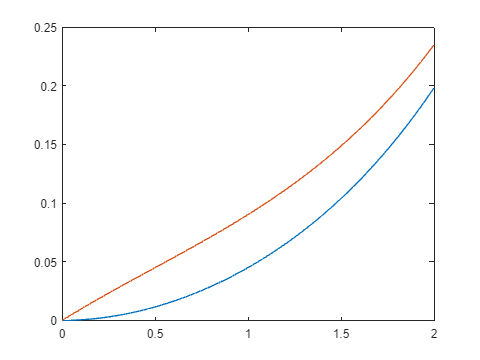


plot(x,y)

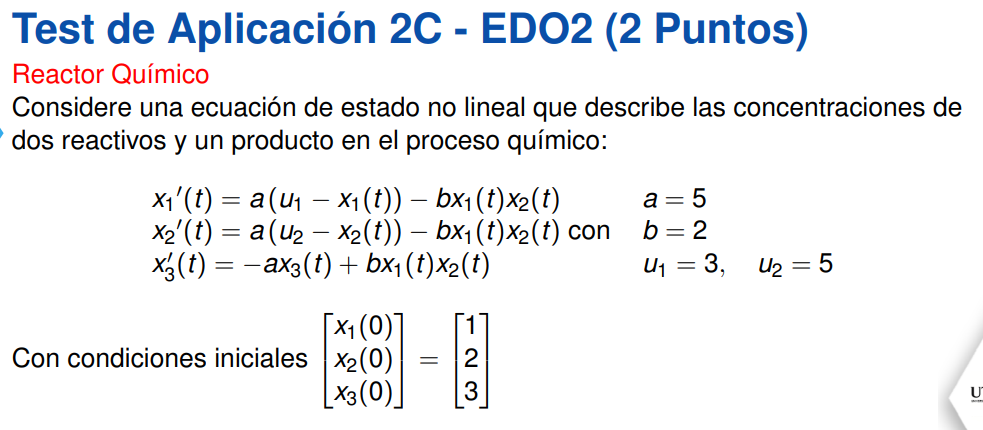

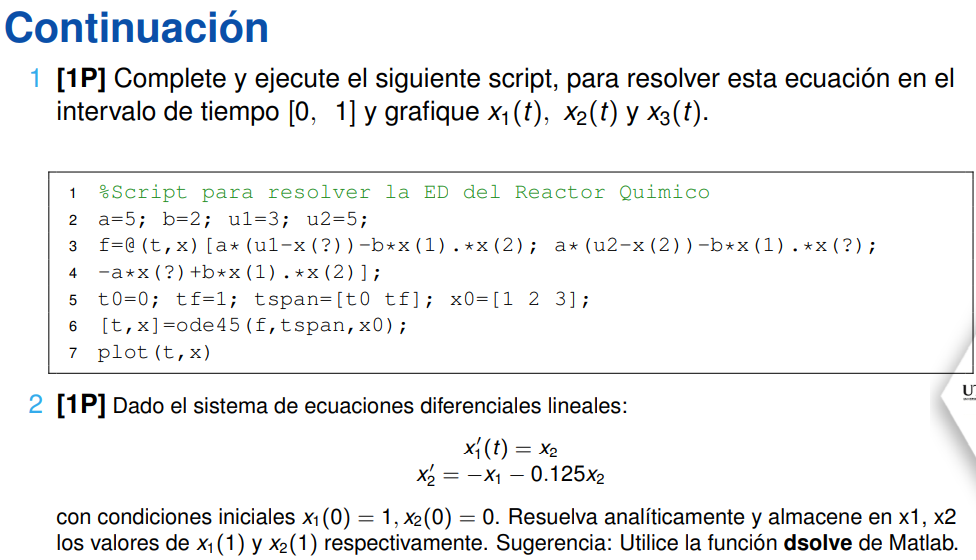

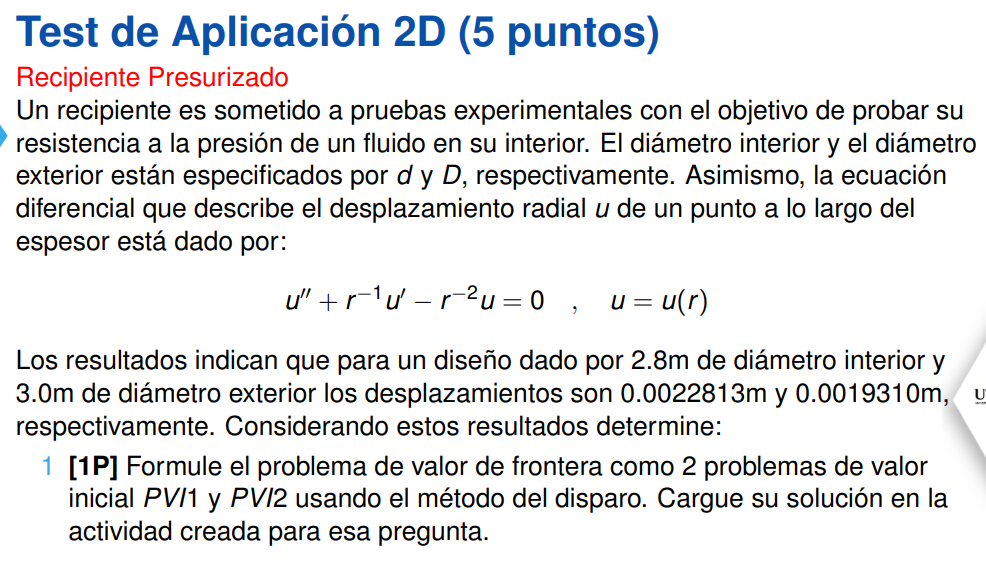

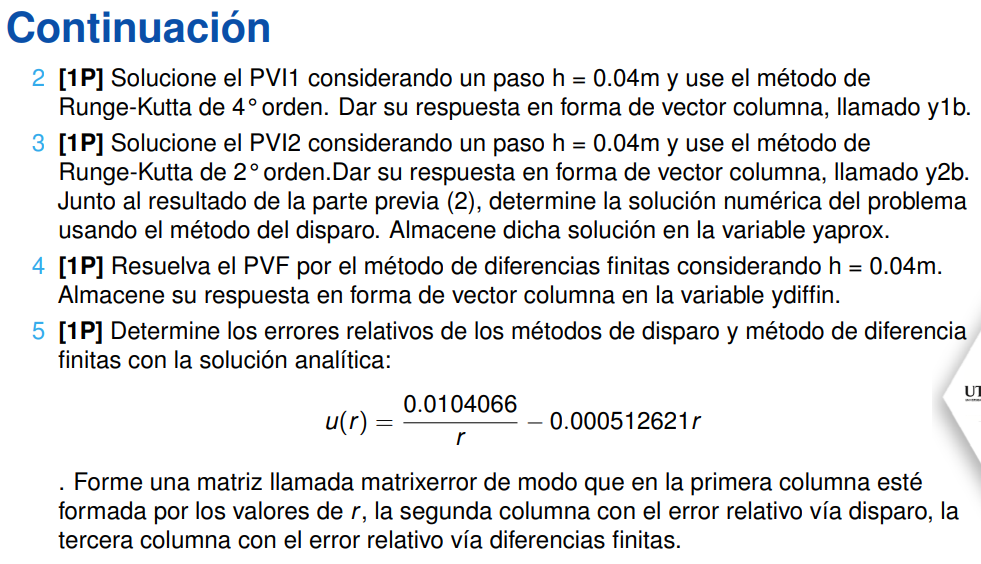

# Funciones

2A.1. Spline Cúbico Natural

function S = splinenatural(X,Y)
    N = length(X)-1;
    H = diff(X);
    E = diff(Y)./H;
    diagprinc = 2*(H(1:N-1)+H(2:N));
    diagsupinf = H(2:N-1);
    g0 = 0; 
    gn = 0;
    A = diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b = 6*diff(E');
    g = A\b;
    g = [g0 g' gn];

    for i = 1:N
        S(i,1) = (g(i+1)-g(i))/(6*H(i));
        S(i,2) = g(i)/2;
        S(i,3) = E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4) = Y(i);
        xx = linspace(X(i),X(i+1),100);
        yy = S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy)
        hold on
    end
    grid on
    %hold off
end

2A.1. Método de Newton con tolerancia

function z = newton(f,x0,Tol)
    syms x
    df = diff(f(x));
    dfu = matlabFunction(df);
    z = x0;
    error = 1;

    while error > Tol
        x1 = x0 - f(x0)/dfu(x0);
        z = [z; x1];
        error = abs(x1-x0)/abs(x1);
        x0 = x1;
    end
end